%%PROGRAMA PRINCIPAL 

alpha = 1/sqrt(2)

alpha = 0.7071

PA = [alpha 0 0 -1 -alpha 0 0 0 0 0 0 0 0;
       0 1 0 0 0 -1 0 0 0 0 0 0 0;
       0 0 1 0 0 0 0 0 0 0 0 0 0;
       alpha 0 1 0 alpha 0 0 0 0 0 0 0 0;
       0 0 0 1 0 0 0 -1 0 0 0 0 0;
       0 0 0 0 alpha 1 0 0 -alpha -1 0 0 0;
       0 0 0 0 0 0 1 0 0 0 0 0 0;
       0 0 0 0 0 0 0 1 alpha 0 0 -alpha 0;
       0 0 0 0 alpha 0 1 0 alpha 0 0 0 0;
       0 0 0 0 0 0 0 0 0 1 0 0 -1;
       0 0 0 0 0 0 0 0 0 0 1 0 0;
       0 0 0 0 0 0 0 0 alpha 0 1 alpha 0;
       0 0 0 0 0 0 0 0 0 0 0 -alpha 1]

PA =     0.7071         0         0   -1.0000   -0.7071         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0   -1.0000         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0         0
    0.7071         0    1.0000         0    0.7071         0         0         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0   -1.0000         0         0         0         0         0
         0         0         0         0    0.7071    1.0000         0         0   -0.7071   -1.0000         0         0         0
         0         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0    1.00

   
   Pb = [ 0 0 10 0 0 0 0 0 15 0 20 0 0]'

Pb =      0
     0
    10
     0
     0
     0
     0
     0
    15
     0


   
 %================================================================================== 

 [DIAG, ENV_sup, ENVcol_sup, ENVlin_sup, ENV_inf, ENVcol_inf, ENVlin_inf]= matrizParaEnvelope(PA)

DIAG =     0.7071    1.0000    1.0000         0         0    1.0000    1.0000    1.0000    0.7071    1.0000    1.0000    0.7071    1.0000


ENV_sup =    -1.0000         0         0   -0.7071         0         0    0.7071   -1.0000         0         0         0   -1.0000         0         0   -0.7071         0    0.7071   -1.0000         0         0         0   -0.7071         0         0         0   -1.0000         0         0         0


ENVcol_sup =      1     1     1     1     4     8    12    12    15    18    22    22    26    29


ENVlin_sup =      1     2     3     1     2     3     4     2     3     4     5     5     6     7     6     7     8     6     7     8     9     8     9    10    11    10    11    12     0


ENV_inf =     0.7071         0    1.0000    1.0000    0.7071    0.7071         0    1.0000         0    0.7071         0    1.0000   -0.7071         0


ENVcol_inf =      1     2     3     4     5     5     6     7     8     9    10    11    12     0


ENVlin_inf =      1     1     1     1     4     5     6     6     6    10    10    10    13    14


 
 n = size(DIAG,2)

n = 13

 %==================================================================================
 
 %notação adotada
 
 %Ak = matriz (k+1)x(k+1)
 
 %matriz caso base é Ak = [PA(1,1)]
 
 %A(k+1) = [Ak   b;            = [Lk   0(coluna); = [Uk        u;     
 %          c'    a(k+2)(k+2)];   e'   1];           0(linha)  u(k+2)(k+2)];     
 
 %c é vetor coluna (k+1)x1 e b também é vetor coluna (k+1)x1
 
 %===================================================================================
 %k = 0;
 
    %Lk e Uk em formato de matriz full
     Lk = 1;
     Uk = DIAG(1,1);
     
     %Lk e Uk em formato envelope por linha e coluna, respectivamente
     %L0 = [1]; U0 = [PA11] = DIAG(1)
     DIAG_L = [1];
     ENV_inf_L = [0];
     ENVlin_inf_L = [1];
     ENVcol_inf_L = [0];
        
     DIAG_U = DIAG(1,1);
     ENV_sup_U = [0];
     ENVcol_sup_U = [1];
     ENVlin_sup_U = [0];
 
 for k = 0:(n-2)%é isso mesmo
     
     %envelopes auxiliares -> envelopes de A(k+1) (matriz (k+2)x(k+2))
     %[~, ENV_sup_aux, ENVcol_sup_aux, ENVlin_sup_aux, ENV_inf_aux, ENVcol_inf_aux, ENVlin_inf_aux] = matrizParaEnvelope(PA(1:(k+2),1:(k+2)))
      
     %calculando b, c e a(k+2)(k+2) em A(k+1)
     a = DIAG(k+2);%tava em (k+2)
     %a = PA(k+2,k+2)
     b = zeros(k+1, 1);
     c = zeros(k+1, 1);
     
     %=================================================================================
     
     %obtendo b
     numerosNaoNulosB = ENVcol_sup(k+3)-ENVcol_sup(k+2);
     posicao_inicial_b = ENVcol_sup((k+2));
     for i = 1:numerosNaoNulosB
        linha = ENVlin_sup(posicao_inicial_b+(i-1));
        b(linha) = ENV_sup(posicao_inicial_b+(i-1));
         
     end
     
     %=================================================================================
     
     %obtendo c
     numerosNaoNulosC = ENVlin_inf(k+3)-ENVlin_inf(k+2);
     posicao_inicial_c = ENVlin_inf((k+2));
     for i = 1:numerosNaoNulosC
        coluna = ENVcol_inf(posicao_inicial_c+(i-1));
        c(coluna) = ENV_inf(posicao_inicial_c+(i-1));
         
     end
     
     %=================================================================================
      
     %resolvendo os sistemas auxiliares
     
     %(1) Lk*u = b
     u = resolverTriangularInferior(DIAG_L, ENV_inf_L, ENVlin_inf_L, ENVcol_inf_L, b); %%pra k=0:L = 1, b=0
     
     %(2) Uk'*e = c
     e = resolverTriangularInferior(DIAG_U, ENV_sup_U, ENVcol_sup_U, ENVlin_sup_U, c); %%pra k=0: U = alpha, c=0 
     
     %=================================================================================
    
     %agora vamos computar u(k+2)(k+2) que será chamado de ukMAIS2
     ukMais2 = a - e'*u;
      
     %=================================================================================
    
     %o passo seguinte é a atualização dos envelopes de L e U
     
     %primeiro vamos atualizar o envelope de L (Lk -> Lk "+" "e" + "1") 
     %lembrando da nossa notação: Lk=[Lk zeros(k+1,1); e' 1];
     
     Lk=[Lk zeros(k+1,1);... 
         e' 1];
     
     %DIAG_L = [DIAG_L 1]
    
     [DIAG_L, ~, ~, ~, ENV_inf_L, ENVcol_inf_L, ENVlin_inf_L] = matrizParaEnvelope(Lk);
     
     
     %só resta atualizar U (Uk -> Uk + "u" + "ukMais2")
     %lembrando da nossa notação: Uk=[Uk u;  zeros(1,k+1) ukMais2];
     Uk=[Uk u;...
         zeros(1,k+1) ukMais2];
     
     %DIAG_U = [DIAG_U ukMais2];
     
     [DIAG_U, ENV_sup_U, ENVcol_sup_U, ENVlin_sup_U, ~, ~, ~] = matrizParaEnvelope(Uk);
     
 end
 %=================================================================================
 Pb

Pb =      0
     0
    10
     0
     0
     0
     0
     0
    15
     0


 L = Lk

L =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000    1.0000         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0   -0.5000    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0    1.000

 U = Uk

U =     0.7071         0         0   -1.0000   -0.7071         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0   -1.0000         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000    1.4142         0         0         0         0         0         0         0         0
         0         0         0         0   -1.4142         0         0   -1.0000         0         0         0         0         0
         0         0         0         0         0    1.0000         0   -0.5000   -0.7071   -1.0000         0         0         0
         0         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0    1.000

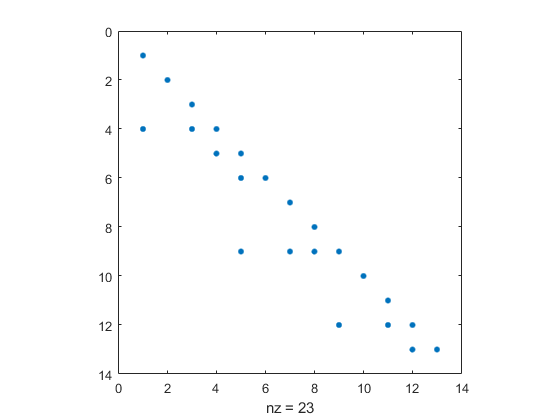

 spy(L)

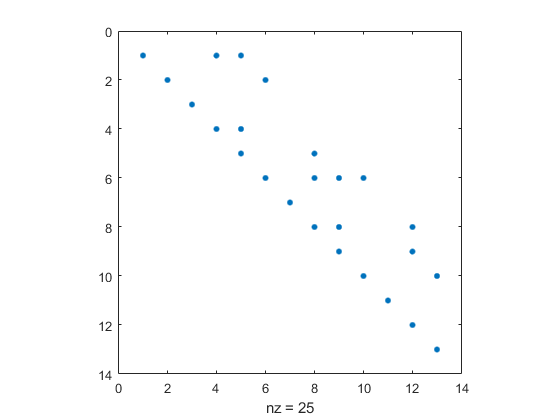

 spy(U)

 

 %=================================================================================
 
 %finalmente vamos resolver os sitemas auxiliares com L e U da matriz PA inicial
 %(1)Ly = b  e (2)Ux = y
 
 y = resolverTriangularInferior(DIAG_L, ENV_inf_L, ENVlin_inf_L, ENVcol_inf_L, Pb)

y =      0
     0
    10
   -10
    10
     5
     0
     0
    20
     0


 %y_certo = L\Pb
 %e por fim...
 
 x = resolverTriangularSuperior(DIAG_U, ENV_sup_U, ENVcol_sup_U, ENVlin_sup_U, y)

x =   -28.2843
  -30.0000
   10.0000
  -30.0000
   14.1421
  -30.0000
         0
  -30.0000
    7.0711
  -25.0000


 %x = U\y
 
 